# Electron in Periodic Potential

## Initialisation

clear
Proj = currentProject;

MASK = @(A, M, val) subsasgn(A, struct("type", "()", "subs", {{M}}), val); %#ok<SUBSASGN> 
VECTOR = @(A, dim) reshape(A, [ones(1, dim-1) numel(A) 1]);

NG = 5;
NG1 = 2*NG+1;
Nk = 25;

nG = (-NG:NG).';
O = ones(Nk, 1);
Z = zeros(Nk, 1);
L = linspace(0, 1, Nk).';

## 1D

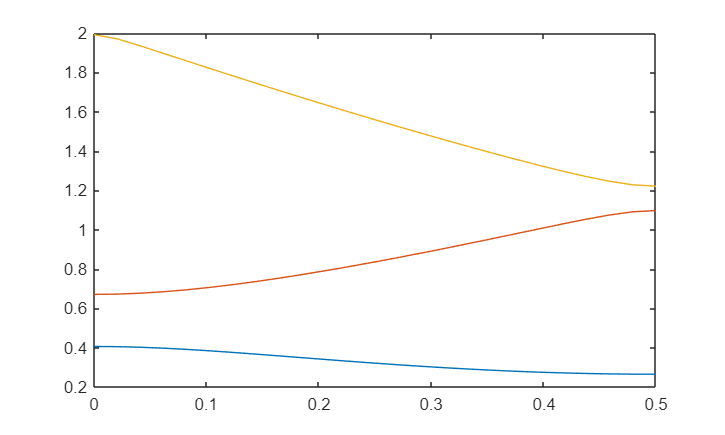

Nk1 = Nk;
k1 = .5*L;
U01 = .25;

E1 = zeros(Nk, NG1);
U1 = U01./(Row(nG)-Column(nG)).^2;
U1(~isfinite(U1)) = 0;
for nk=1:Nk1
	[~, D] = eig(diag(.5*(k1(nk)-nG).^2) + U1);
	E1(nk, :) = diag(D);
end

Figure;
plot(k1, E1(:, 2:4))

## 2D

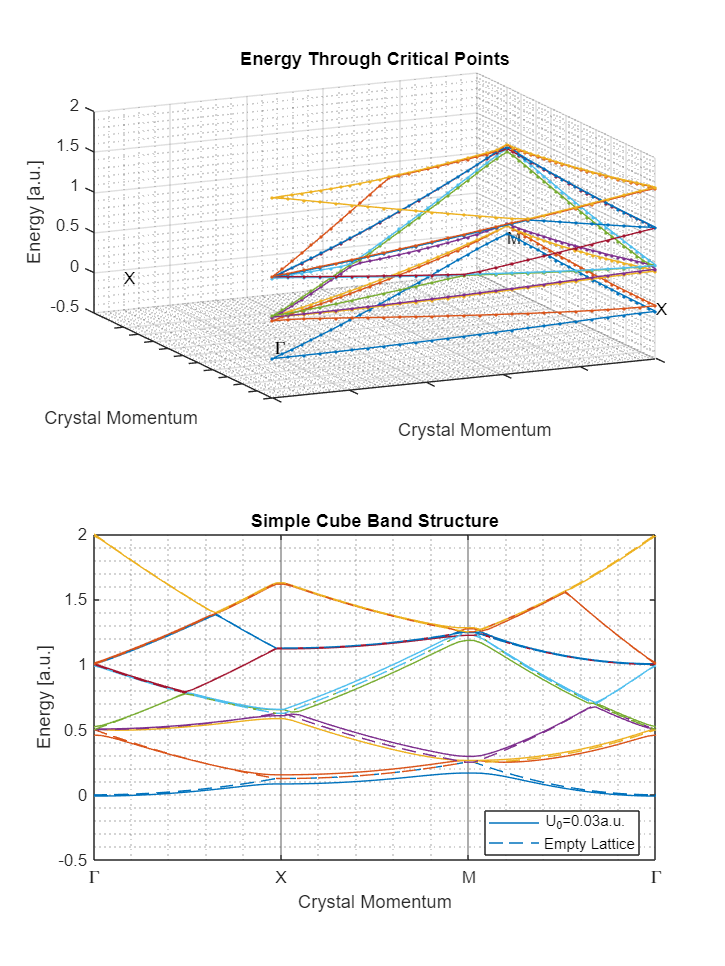

NG2 = NG1^2;
N2 = 3;
Nk2 = N2*Nk;
U02 = .03;

%	Wave vector goes from gamma to X to M to Gamma
k2 = .5*[[L; O; 1-L] [Z; L; 1-L]];

%	G = n1*b1 + n2*b2 with integer n1, n2
G2 = [Column(repmat(Column(nG), [1 NG1])) ...
	Column(repmat(Row(nG), [NG1 1]))];

U2 = -U02./sum((reshape(G2, 1, [], 2)-reshape(G2, [], 1, 2)).^2, 3);
U2(~isfinite(U2)) = 0;

E2 = zeros(Nk2, NG2);
E2_empty = E2;
for nk=1:Nk2
	[~, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)) + U2);
	E2(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k2(nk, :)-G2).^2, 2)));
	E2_empty(nk, :) = diag(D);
end

indE = 1:10;
Emn = min(E2(:, indE), [], "all");

fig = Figure(Width=750, Height=1000);
T = tiledlayout(fig, "Flow");

ax = nexttile(T);
plot3(ax, k2(:, 1), k2(:, 2), E2(:, indE), ".-");
grid on;
grid minor;
xticklabels([]);
yticklabels([]);
text(0, 0, Emn, "\Gamma", "VerticalAlignment", "Bottom");
text(.5, 0, Emn, "X", "VerticalAlignment", "Bottom");
text(.5, .5, Emn, "M", "VerticalAlignment", "Bottom");
text(0, .5, Emn, "X", "VerticalAlignment", "Bottom");
view(-25, 25);
title("Energy Through Critical Points");
xlabel("Crystal Momentum")
ylabel("Crystal Momentum")
zlabel("Energy [a.u.]")

ax = nexttile(T);
h1 = plot(ax, linspace(0, N2, Nk2).', E2(:, indE), "-");
h2 = line(ax, linspace(0, N2, Nk2).', E2_empty(:, indE), ...
	"LineStyle", "--");
xticks(0:N2);
xticklabels(["\Gamma" "X" "M" "\Gamma"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("Simple Square Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U02+"a.u." "Empty Lattice"], ...
	"Location", "Best");


% ax = nexttile(T);
% plot(ax, linspace(0, 3, Nk2).', E2_empty(:, 1:10));
% xticks(0:3);
% xticklabels(["\Gamma" "X" "M" "\Gamma"]);
% grid minor;
% ax.GridAlpha = .5;
% ax.XGrid = "On";
% title("Simple Cube Empty Lattice Band Structure");
% ylabel("Energy [a.u.]");
% xlabel("Crystal Momentum")

## 3D

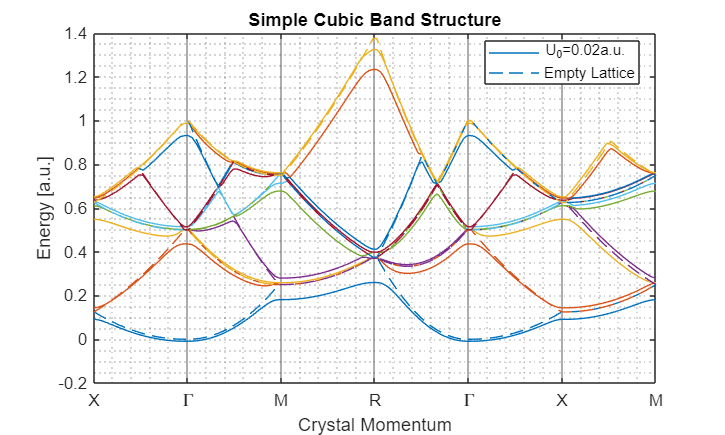

NG3 = NG1^3;
N3 = 6;
Nk3 = N3*Nk;
U03 = .02;

%	Wave vector: X G M R G X M
%	G = [0 0 0]
%	X = [.5 0 0]
%	M = [.5 .5 0]
%	R = [.5 .5 .5]
k3 = .5*[...
	[	1-L;	L;		O;		1-L;	L;		O] ...
	[	Z;		L;		O;		1-L;	Z;		L] ...
	[	Z;		Z;		L;		1-L;	Z;		Z]];

%	G = n1*b1 + n2*b2 with integer n1, n2
G3 = [Column(repmat(Column(nG), [1 NG1 NG1])) ...
	Column(repmat(Row(nG), [NG1 1 NG1])) ...
	Column(repmat(Page(nG), [NG1 NG1 1]))];

U3 = -U03./sum((reshape(G3, 1, [], 3)-reshape(G3, [], 1, 3)).^2, 3);
U3(~isfinite(U3)) = 0;

E3 = zeros(Nk3, NG3);
E3_empty = E3;
for nk=1:Nk3
	[~, D] = eig(diag(.5*sum((k3(nk, :)-G3).^2, 2)) + U3);
	E3(nk, :) = diag(D);

	[~, D] = eig(diag(.5*sum((k3(nk, :)-G3).^2, 2)));
	E3_empty(nk, :) = diag(D);
end

indE = 1:10;
Emn = min(E3(:, indE), [], "all");

fig = Figure;
h1 = plot(linspace(0, N3, Nk3).', E3(:, indE), "-");
h2 = line(linspace(0, N3, Nk3).', E3_empty(:, indE), ...
	"LineStyle", "--");
ax = h1(1).Parent;
xticks(0:N3);
xticklabels(["X" "\Gamma" "M" "R" "\Gamma" "X" "M"]);
ax.GridAlpha = .5;
ax.XGrid = "On";
grid minor;
title("Simple Cubic Band Structure");
ylabel("Energy [a.u.]");
xlabel("Crystal Momentum")
legend([h1(1) h2(1)], ...
	["U_0="+U03+"a.u." "Empty Lattice"], ...
	"Location", "Best");

## Functions

function fig = Figure(Arg)
%	Returns handle to figure window, clears figure and sets its size & units.
arguments
	Arg.Fig = gcf;
	Arg.Width = 1000;
	Arg.Height = 600;
	Arg.Units = "Pixels";
end
fig = Arg.Fig;
clf(fig);
fig.Units = Arg.Units;
fig.Position = [10 50 Arg.Width Arg.Height];
colormap(fig, "turbo");
end
